## Analysis hydrological model

In this model we assume water flow to be natural flow and no human interaction.

We use equation $Q_{S1} +Q_{S2} +F=Q_{S3}$

### Load Dataset

df = readtable('dataset-3b.xlsx', 'Sheet', 'Q1A'  , 'Range', 'A1:F56');
disp(df(1:5,:))

    Day    Height_S1    Discharge_S1    Discharge_S2    Discharge_S3    Height_S3
    ___    _________    ____________    ____________    ____________    _________

     1      117.87         1011.4            1630            3582        114.06  
     2      117.84         1004.8          1627.9            3519        113.97  
     3       117.8            996          1615.3            3442        113.86  
     4      117.74          983.1          1598.5            3365        113.75  
     5      117.66          965.9          1583.8          3297.5        113.65  



### Exploratory Data Analysis

Column descrioption

### Visualization

Q_S1 = df.Discharge_S1;
Q_S2 = df.Discharge_S2;
Q_S3 = df.Discharge_S3;

% compute F constant from equation
F = Q_S3 - Q_S1 - Q_S2;

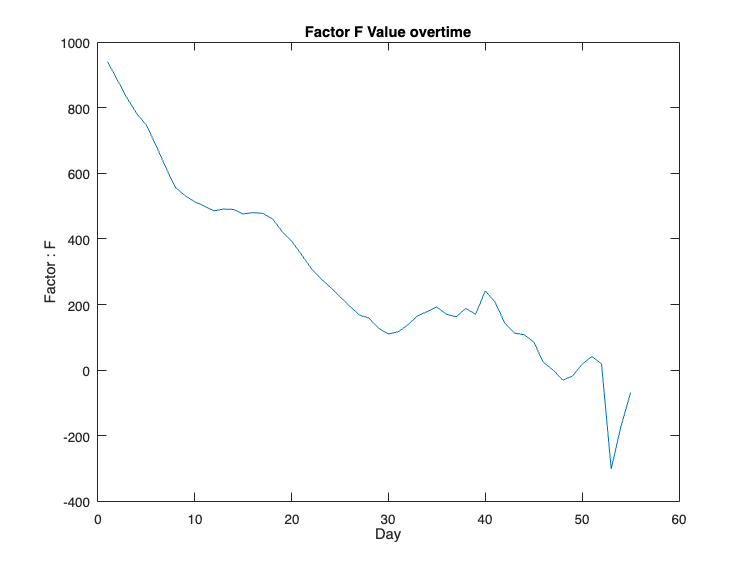

plot(F)
xlabel("Day")
ylabel("Factor : F")
title("Factor F Value overtime")

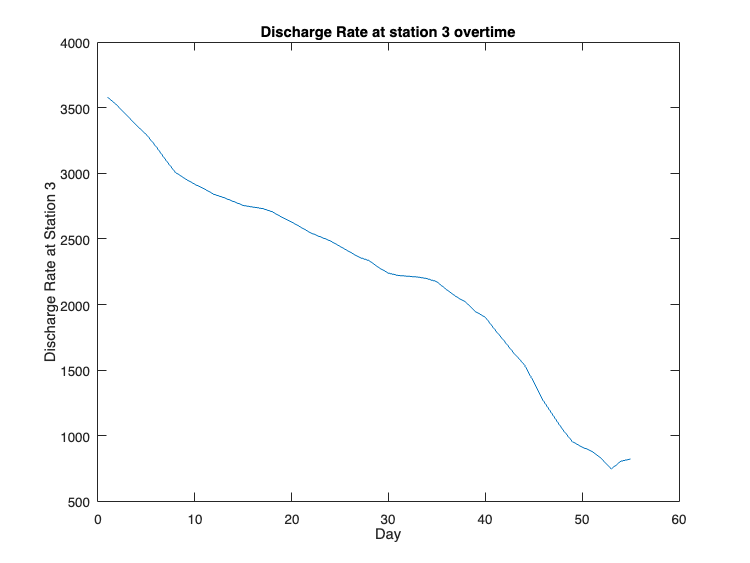

plot(Q_S3)
xlabel("Day")
ylabel("Discharge Rate at Station 3")
title("Discharge Rate at station 3 overtime")

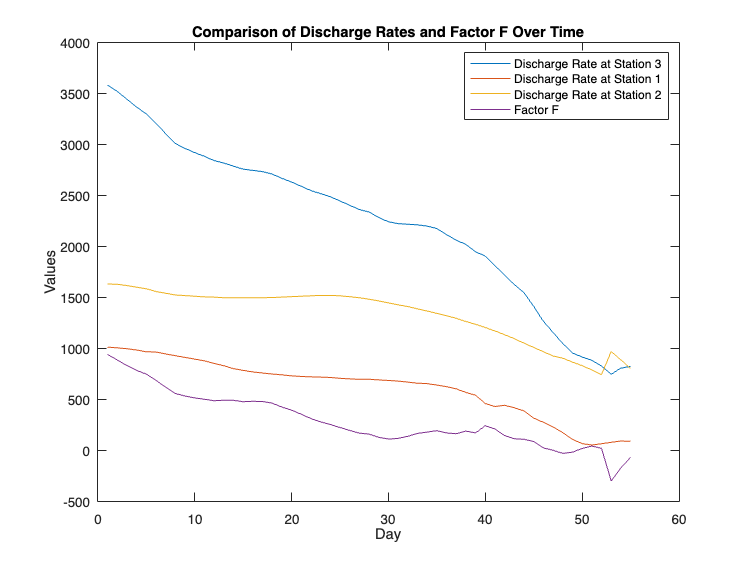

Q_S1 = df.Discharge_S1;
Q_S2 = df.Discharge_S2;
Q_S3 = df.Discharge_S3;

% Compute F constant from equation
F = Q_S3 - Q_S1 - Q_S2;

% Plot Q_S3
plot(Q_S3, 'DisplayName', 'Discharge Rate at Station 3')
hold on; % Retains the current plot for adding more plots

% Plot Q_S1
plot(Q_S1, 'DisplayName', 'Discharge Rate at Station 1')

% Plot Q_S2
plot(Q_S2, 'DisplayName', 'Discharge Rate at Station 2')

% Plot F
plot(F, 'DisplayName', 'Factor F')

hold off; % Release the plot

xlabel("Day")
ylabel("Values")
title("Comparison of Discharge Rates and Factor F Over Time")

legend show % Show legend to distinguish between the lines

% Compute the Pearson correlation coefficient
R = corr(F, Q_S3, 'Type', 'Pearson');

% Display the correlation coefficient
fprintf('Pearson correlation coefficient between F and Q_S3: %f\n', R);

Pearson correlation coefficient between F and Q_S3: 0.923948


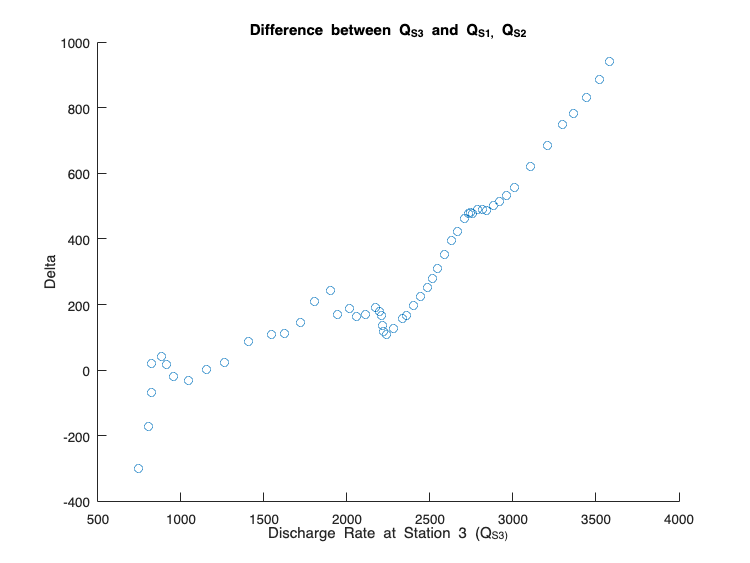

% Scatter plot between Q_S3 and F
scatter(Q_S3, F);
xlabel('Discharge Rate at Station 3 (Q_S3)');
ylabel('Delta');
title("Difference between Q_S3 and Q_S1, Q_S2")

### Simple Hydrologimodel

$Q_{\mathrm{S1}} +Q_{\mathrm{S2}} ={\mathrm{fQ}}_{\mathrm{S3}}$ and f is factor that scale Q_S3 to match with sum of Q_S1 and Q_S2 

we can visualize in the dataset

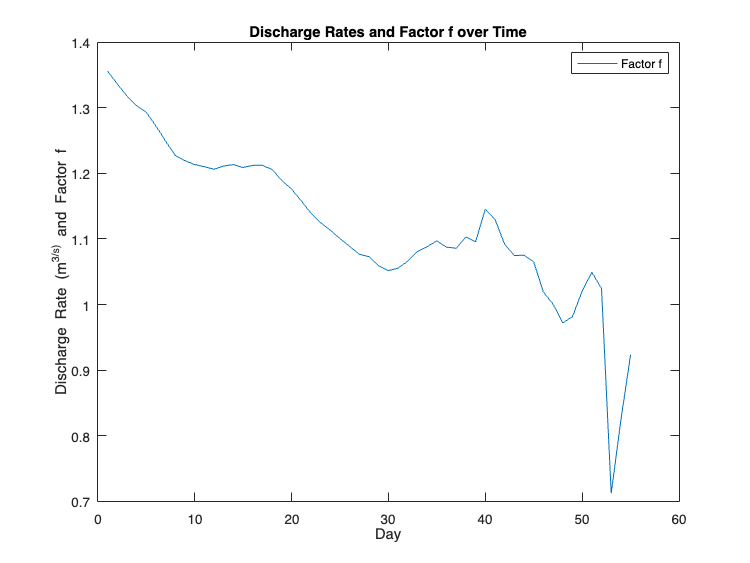

% Calculate the factor f
f = Q_S3 ./ (Q_S1 + Q_S2); % Ensure element-wise division with ./

% Open a new figure window
figure;

% Plotting all variables
plot(f, 'DisplayName', 'Factor f'); % Plot f

% Adding labels and title
xlabel('Day'); % Assuming x-axis represents time or sample index
ylabel('Discharge Rate (m^3/s) and Factor f');
title('Discharge Rates and Factor f over Time');

% Adding a legend
legend('show');

plot(Q_S3)
xlabel("Day")
ylabel("Discharge Rate at Station 3")
title("Discharge Rate at station 3 overtime")